# Cvičení 2 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week02' '\sem'])))
table = readtable('data.csv', 'ReadVariableNames', true);

Prohlédněte si data - hodnoty a jejich popisky - přístupem ke sloupcům v tabulce:

data = table.VOT;           % Hodnoty - data
labels = table.subject;     % Popisky - labels
nBins = 16;

## 1. Vykreslení histogramu, výpočet deskriptivních statistik

- Průměr

- Směrodatná odchylka

- Medián

- Mediánová absolutní odchylka (MAD)

- Trim-mean (procenta zvolte a udejte)

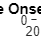

figure(1)
histogram(data, nBins)
grid on
xlabel('VOT [s]')
ylabel('Count [-]')
title('Histogram - Voice Onset Time (HC, PSP, HN)')


dataStandardDeviation = std(data);
fprintf('Standard deviation is %.2f\n', dataStandardDeviation)

Standard deviation is 7.75


dataMean = mean(data);
fprintf('Mean is %.2f\n', dataMean)

Mean is 21.99


dataMedian = median(data);
fprintf('Median is %.2f\n', dataMedian)

Median is 19.82


dataMedianDeviation = mad(data, 1);
fprintf('MAD is %.2f\n', dataMedianDeviation)

MAD is 3.90


trimPercentage = 25;
dataTrimMean = trimmean(data, trimPercentage);
fprintf('%d%% trimmed mean is %.2f\n', trimPercentage, dataTrimMean)

25% trimmed mean is 20.53


## 2. Histogram s PDF a median-based PDF

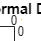

xRange = linspace(0, 2*dataMean);
dataPDF = normpdf(xRange, dataMean, dataStandardDeviation);
dataMedianPDF = normpdf(xRange, dataMedian, 1.48*dataMedianDeviation);

figure(2)
histogram(data, nBins, 'Normalization', 'pdf')
hold on
plot(xRange, dataPDF, 'LineWidth', 2)
plot(xRange, dataMedianPDF, 'LineWidth', 2)
hold off
grid on
xlabel('VOT [s]')
ylabel('Count [-]')
legend('VOD Histogram', 'Mean/Std Normal PDF', 'Median/MAD Normal PDF')
title('Histogram + Fitted Normal Distribution (manually)')

## 3. Histogram s KDE (Kernel Density Estimation)

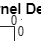

BW = min(dataStandardDeviation, iqr(data)/1.35)*0.9*length(data)^(-1/5);

kernel = zeros(length(data), length(xRange));
for i = 1:length(data)
    kernel(i,:) = normpdf(xRange, data(i), BW);
end
KDE = sum(kernel, 1)/length(data);

figure(3)
histogram(data, nBins, 'Normalization', 'pdf')
hold on
plot(xRange, KDE, 'LineWidth', 2)
hold off
grid on
xlabel('VOT [s]')
ylabel('Count [-]')
legend('VOD Histogram', 'Kernel Density Estimation')
title('Histogram + Kernel Density Estimation')

## 4. Určení outlierů pomocí 68-95-99.7 pravidla, vykreslení CDF, nalezení outlierů a hranice

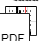

confidenceIntervals = [
    dataMean-3*dataStandardDeviation;
    dataMean-2*dataStandardDeviation;
    dataMean-dataStandardDeviation;
    dataMean;
    dataMean+dataStandardDeviation;
    dataMean+2*dataStandardDeviation;
    dataMean+3*dataStandardDeviation
];
confidenceIntervalsLabels = {
    '\mu-3\sigma';
    '\mu-2\sigma';
    '\mu-\sigma';
    '\mu';
    '\mu+\sigma';
    '\mu+2\sigma';
    '\mu+3\sigma'
};
threshold = 35;

% PDF
figure(4)
histogram(data, nBins, 'Normalization', 'pdf')
hold on
plot(xRange, dataPDF, 'LineWidth', 2)
xline(confidenceIntervals, ':')
xline(threshold, '-r')
hold off
grid on
xlim([-10 60])
xlabel('VOT [s]')
ylabel('Count [-]')
legend('VOD Histogram', 'Mean/Std Normal PDF', 'Confidence intevals', 'Location', 'northeast')
mainAxes = gca;
mainAxes.Position = mainAxes.Position.*[1, 1, 1, .9];
secondaryAxes = axes('Position', get(mainAxes,'Position'), ...
    'XAxisLocation','top', ...
    'XTick', confidenceIntervals, ...
    'XTickLabel', confidenceIntervalsLabels, ...
    'Color','none', ...
    'XColor','k');
secondaryAxes.YAxis.Visible = 'off';
secondaryAxes.XLim = mainAxes.XLim;
t = title('Histogram with normal confidence intervals');
set(t, 'Position', get(t, 'Position').*[1, 1.02, 1])

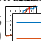


% CDF
figure(5)
cdfplot(data)
title('')
hold on
plot(xRange, cdf('Normal', xRange, dataMean, dataStandardDeviation));
xline(confidenceIntervals, ':')
xline(threshold, '-r')
hold off
xlabel('VOT [s]')
ylabel('Probability [-]')
legend('Empirical CDF', 'Normal CDF', 'Confidence intervals', 'Location', 'northwest')
mainAxes = gca;
mainAxes.Position = mainAxes.Position.*[1, 1, 1, .9];
secondaryAxes = axes('Position', get(mainAxes,'Position'), ...
    'XAxisLocation','top', ...
    'XTick', confidenceIntervals, ...
    'XTickLabel', confidenceIntervalsLabels, ...
    'Color','none', ...
    'XColor','k');
secondaryAxes.YAxis.Visible = 'off';
secondaryAxes.XLim = mainAxes.XLim;
t = title('Histogram with normal confidence intervals');
set(t, 'Position', get(t, 'Position').*[1, 1.02, 1])

Interval $\left(\mu -2\sigma ,\mu +2\sigma \right)$ představuje standardní konfidenční interval 95 %, na základě čehož můžeme označit hodnoty mimo tento interval jako outliery. V případě našich dat tedy za outliery pokládáme hodnoty ležící za červenou vertikální čarou v grafech výše.

## 5. Vyjmutí extrémů, znovu výpočet deskriptivních statistik, vykreslení histogramu s PDF

% Remove outliers
trimmedData = data(data < threshold);

% Calculate descriptive statistics
trimmedDataStandardDeviation = std(trimmedData);
fprintf('Standard deviation is %.2f\n', trimmedDataStandardDeviation)

Standard deviation is 4.36


trimmedDataMean = mean(trimmedData);
fprintf('Mean is %.2f\n', trimmedDataMean)

Mean is 19.97


trimmedDataMedian = median(trimmedData);
fprintf('Median is %.2f\n', trimmedDataMedian)

Median is 19.33


trimmedDataMedianDeviation = mad(trimmedData, 1);
fprintf('MAD is %.2f\n', trimmedDataMedianDeviation)

MAD is 3.68


trimmedDataTrimMean = trimmean(trimmedData, trimPercentage);
fprintf('%d%% trimmed mean is %.2f\n', trimPercentage, trimmedDataTrimMean)

25% trimmed mean is 19.76



% Plot histogram with normal PDFs
xRange = linspace(0, 2*trimmedDataMean);
trimmedDataPDF = normpdf(xRange, trimmedDataMean, trimmedDataStandardDeviation);
trimmedDataMedianPDF = normpdf(xRange, trimmedDataMedian, 1.48*trimmedDataMedianDeviation);

figure(6)
histogram(trimmedData, nBins, 'Normalization', 'pdf')
hold on
plot(xRange, trimmedDataPDF, 'LineWidth', 2)
plot(xRange, trimmedDataMedianPDF, 'LineWidth', 2)
hold off
grid on
xlim([xRange(1), xRange(end)])
xlabel('VOT [s]')
ylabel('Count [-]')
legend('VOD Histogram', 'Mean/Std Normal PDF', 'Median/MAD Normal PDF')
title('Histogram + Fitted Normal Distribution (manually)')

## 6. Odpovědi na otázky

- *Jak moc se odhadnuté distribuce liší pro data s a data bez extrémních hodnot?*

- *Které statistické parametry jsou citlivé na výskyt extrémních hodnot?*

- *Které statistické parametry jsou naopak velmi robustní?*

- Po odstranění extrémních hodnot se zlepšila korespondence odhadnutých distribucí s naměřenými daty. Krom toho můžeme také pozorovat, že se méně rozchází *Mean/STD Normal PDF *s *Median/MAD Normal Distribution*, což odpovídá známému poznatku, že medián je méně zatížen vlivem odlehlých hodnot ve statistickém souboru.

- Střední hodnota, směrodatná odchylka

- Medián, MAD, trim-mean

## Nepovinný bonus

Vygenerujte si libovolný počet $M$ náhodných vektorů o délce $L$ z libovolného nenormálního  rozdělení . Tyto vektory složte do matice o velikosti $L\times M$ nebo $M\times L$ (záleží, zda jsou  vaše vektory sloupcové nebo řádkové). Vektory samozřejmě můžete vygenerovat i jedním  příkazem jako matici $L\times M$. 

Hodnoty přes jednotlivé vektory zprůměrujte a vykreslete histogram výsledného vektoru.  Vyzkoušejte si různé počty vektorů $M$ (např. 2,3,5, 100) a různé délky$L$. Měli byste tím získat  aproximaci normálního rozdělení. V praxi si tak zkusíte efekt centrální limitní věty, která  je podle mnohých odpovědí na otázku, proč je normální rozdělení v přírodě tak hojné.

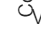

L = 1000;
M = [2, 3, 5, 25, 1e2, 1e3];
gammaDist = makedist('Gamma');
figure(7)
fig = tiledlayout(2,3);
for i = 1:length(M)
    matrix = random(gammaDist, [L, M(i)]);
    average = sum(matrix, 2)/M(i);

    nexttile
    histogram(average)
    title(['LxM = ' num2str(L) 'x' num2str(M(i))])
end
title(fig,'Gamma distribution')
xlabel(fig, 'Value (-)')
ylabel(fig, 'Count (-)')

#### Zodpovězte následující otázku:

- *Jak souvisí počet zprůměrovaných vektorů s tím, jak moc se výsledné rozdělení bude blížit normálnímu rozdělení?*

Se zvyšujícím se počtem průměrovaných vektorů se zlepšuje aproximace normálního rozdělení. CLT je z definice limitní věta, a tak se k matematicky exaktní rovnosti můžeme pouze přiblížit, ale již pro nevelké hodnoty je vidět tendence velmi dobře.